## 一、基本要求

### 1.数据准备与函数封装

本部分编写的三个函数以相应作用如下：

- fetchTushareStockData：输入股票代码和起止日期，从Tushare平台抓取指定日期范围内的股票数据（包含日期、开盘价、最高价、最低价、收盘价），存储为stockData(timetable)用于后续分析；

- stockAnalysis：由stockData计算MA20、MA60以及买卖信号

- generalStockAnalysis：实现fetchTushareStockData和stockAnalysis的合并，由输入股票代码和日期输出MA20、MA60以及买卖信号；

#### fetchTushareStockData

function stockData = fetchTushareStockData(pro, tsCode, startDate, endDate)
    % function:指定起止日期，从Tushare获取股票数据并转换为timetable格式
    % input:api密钥，股票代码，开始日期，结束日期
    % output:timetable格式的股票数据（包含日期、开盘价、最高价、最低价、收盘价）
    
    result = pro.query('daily', 'ts_code', tsCode, 'start_date', startDate, 'end_date', endDate);
    
    if isempty(result)
        stockData = [];
        return;
    end
    
    % 转换日期格式
    dates = datetime(result.trade_date, 'InputFormat', 'yyyyMMdd');
    
    % 按日期正序排列
    [~, idx] = sort(dates);
    dates = dates(idx);
    open = result.open(idx);
    high = result.high(idx);
    low = result.low(idx);
    close = result.close(idx);
    
    % 创建timetable
    stockData = timetable(dates, open, high, low, close, ...
        'VariableNames', {'Open', 'High', 'Low', 'Close'});
    stockData.Properties.DimensionNames{1} = 'Date';
end


#### stockAnalysis

function result = stockAnalysis(stockData)
    % function:由股票数据计算MA20、MA60以及买卖信号；
    % input:有fetchTushareStockData提取得到的股票数据
    % output:结构体result（包括MA20(211*1)，MA60(211*1)，买入信号（211*1，逻辑序列）和卖出信号（211*1，卖出信号）
    
    closePrice = stockData.Close;
    
    % 计算移动平均线
    result.MA20 = movmean(closePrice, 20, 'omitnan');
    result.MA60 = movmean(closePrice, 60, 'omitnan');
    
    % 检测金叉：MA20从下向上穿越MA60
    ma20_prev = [NaN; result.MA20(1:end-1)];
    ma60_prev = [NaN; result.MA60(1:end-1)];
    goldenCross = (result.MA20 > result.MA60) & (ma20_prev <= ma60_prev) & ~isnan(ma20_prev) & ~isnan(ma60_prev);
    
    % 检测死叉：MA20从上向下穿越MA60
    deathCross = (result.MA20 < result.MA60) & (ma20_prev >= ma60_prev) & ~isnan(ma20_prev) & ~isnan(ma60_prev);
    
    result.BuySignals = goldenCross;
    result.SellSignals = deathCross;
end

遇到的问题及解决方案：

- 如何处理序列中开始的若干天和末尾的若干天存在数据不全的情况：此处使用"omitnan"参数忽略缺失值，使得输出的结果长度和输入的数据长度一致；

- 如何定义金叉和死叉：须同时满足前后两天MA20和MA60的大小情况相反，以及前一天不是序列首项。

#### generalStockAnalysis

function result = generalStockAnalysis(pro, stockCode, startDate, endDate)
    % function:综合以上两个函数的作用，直接由股票代码和起止日期生成result。
    % input:api密钥，股票代码，开始日期，结束日期
    % output:结构体result（包括MA20(211*1)，MA60(211*1)，买入信号（211*1，逻辑序列）和卖出信号（211*1，逻辑序列））
    
    % 转换日期格式
    start_date = sprintf('%04d%02d%02d', year(startDate), month(startDate), day(startDate));
    end_date = sprintf('%04d%02d%02d', year(endDate), month(endDate), day(endDate));
    
    % 获取股票数据
    stockData = fetchTushareStockData(pro, stockCode, start_date, end_date);
    
    if isempty(stockData)
        result = [];
        return;
    end
    
    % 执行分析
    analysisResult = stockAnalysis(stockData);
    
    % 组装结果
    result.Data = stockData;
    result.MA20 = analysisResult.MA20;
    result.MA60 = analysisResult.MA60;
    result.BuySignals = analysisResult.BuySignals;
    result.SellSignals = analysisResult.SellSignals;
end

## 2.数据可视化

本部分包含一个画图函数：

- plotStrategy2:绘制2025年自选股票（“贵州茅台”）的蜡烛图，同时叠绘MA20和MA60的图线，标注金叉和死叉和对应日期

function plotStrategy2(stockData, result, stockName)
    % function:绘制2025股票数据的蜡烛图，并叠绘平滑曲线和买卖信号
    % input:fetchTushareStockData生成的stockData,generalStockAnalysis得到的result和StockName
    % output:图像

    dates = stockData.Date;
    open  = stockData.Open;
    high  = stockData.High;
    low   = stockData.Low;
    close = stockData.Close;

    n = numel(dates);
    x = 1:n;   % 用数字索引当横坐标

    figure('Position', [100, 100, 1200, 600]);

    % 蜡烛图
    candle(open, high, low, close , 'k');

    hold on;
    % 添加蜡烛图说明用的虚拟图例
    % 下跌日：黑色实心方块（开盘 > 收盘）
    candle_h1 = plot(NaN, NaN, 'ks', 'MarkerFaceColor', 'k', 'DisplayName', '跌：开盘 > 收盘');
    
    % 上涨日：黑色空心方块（收盘 > 开盘）
    candle_h2 = plot(NaN, NaN, 'ks', 'MarkerFaceColor', 'none', 'DisplayName', '涨：收盘 > 开盘');
    
    hold on;
    % 均线：x 用 1:n 
    h1 = plot(x, result.MA20(:), 'b-', 'LineWidth', 1.5, 'DisplayName', 'MA20');
    h2 = plot(x, result.MA60(:), 'r--','LineWidth', 1.5, 'DisplayName', 'MA60');

    % --- 买入、卖出信号：同理用 x 索引 ---
    buyIdx = find(result.BuySignals);
    if ~isempty(buyIdx)
        scatter(x(buyIdx), close(buyIdx), 100, 'g^', 'filled', ...
            'MarkerEdgeColor','k','LineWidth',1.5,'DisplayName','买入');
        % 文字建议用循环画，防止错位
        for i = 1:numel(buyIdx)
            text(x(buyIdx(i)), close(buyIdx(i))*1.02, ...
                datestr(dates(buyIdx(i)),'mm/dd'), ...
                'FontSize', 8, 'Color','g','HorizontalAlignment','center');
        end
    end

    sellIdx = find(result.SellSignals);
    if ~isempty(sellIdx)
        scatter(x(sellIdx), close(sellIdx), 100, 'rv', 'filled', ...
            'MarkerEdgeColor','k','LineWidth',1.5,'DisplayName','卖出');
        for i = 1:numel(sellIdx)
            text(x(sellIdx(i)), close(sellIdx(i))*0.98, ...
                datestr(dates(sellIdx(i)),'mm/dd'), ...
                'FontSize', 8, 'Color','r','HorizontalAlignment','center');
        end
    end

    % --- 设置 x 轴显示为日期字符串 ---
    xticksIdx = 1:round(n/10):n;  % 每隔大约 n/10 取一个刻度
    set(gca,'XTick',xticksIdx,...
            'XTickLabel',cellstr(datestr(dates(xticksIdx),'yyyy-mm-dd')));

    title([stockName, '2025年金叉死叉策略分析'], 'FontSize', 14, 'FontWeight', 'bold');
    xlabel('日期'); ylabel('价格');
    legend([candle_h1,candle_h2,h1 h2], {'跌：开盘 > 收盘', '涨：收盘 > 开盘','MA20', 'MA60'}, 'Location', 'best');
    legend('AutoUpdate','off');

    grid on;

end


遇到的问题及解决方法：

- 叠绘蜡烛图和移动平滑曲线时，如果candle输入形式是table或者timetable形式的，而移动曲线的数据是数值形式的，两者横坐标有冲突：将传入candle的数据改为double形式的（需注意列分别为open, high, low, close），同时通过（x=1:n)，将数字索引作为横坐标。

- 信号点标注时的数据格式需要转换：先将datatime形式的dates(xticksIdx）转化为字符串型（矩阵），又因多行label需要cell数组，因此再将字符串矩阵转换为cell数组。

### 3.结果展示

最终端到端的输出代码如下：

#### analyzeSingleStock

% 单只股票MA金叉策略分析
% 以贵州茅台为例，演示单只股票的分析流程
% 实现输入股票代码和api密钥，即可得到result和可视化图像

% 初始化Tushare API
token = '6472c06bea19147509d499b9caf7532cc5dcfea007bcd573568d8bd7';  
pro = pro_api(token);

% 股票代码和名称
stockCode = '600519.SH';
stockName = '贵州茅台';

% 日期范围（2025年）
startDate = datetime('2025-01-01');

           Data: [212×4 timetable]
           MA20: [212×1 double]
           MA60: [212×1 double]
     BuySignals: [212×1 logical]
    SellSignals: [212×1 logical]



endDate = datetime('2025-12-31');

   1.0e+03 *

    1.4553
    1.4545
    1.4545
    1.4561
    1.4570
    1.4559
    1.4551
    1.4540
    1.4529
    1.4503
    1.4485
    1.4459
    1.4437
    1.4426
    1.4427
    1.4439
    1.4454
    1.4472
    1.4487
    1.4497
    1.4498
    1.4519
    1.4531
    1.4521
    1.4517
    1.4539
    1.4568
    1.4593
    1.4611
    1.4642
    1.4689
    1.4731
    1.4777
    1.4842
    1.4892
    1.4928
    1.5005
    1.5088
    1.5162
    1.5235
    1.5300
    1.5343
    1.5395
    1.5455
    1.5513
    1.5565
    1.5607
    1.5644
    1.5687
    1.5728
    1.5760
    1.5749
    1.5760
    1.5757
    1.5760
    1.5775
    1.5737
    1.5698
    1.5665
    1.5632
    1.5613
    1.5602
    1.5585
    1.5573
    1.5561
    1.5542
    1.5524
    1.5516
    1.5511
    1.5512
    1.5505
    1.5544
    1.5567
    1.5599
    1.5619
    1.5652
    1.5692
    1.5720
    1.5730
    1.5738
    1.5746
    1.5760
    1.5772
    1.5771
    1.5767
    1.5761
    1.5756
    1.5745
    1.5726
    1.5

   1.0e+03 *

    1.4516
    1.4528
    1.4536
    1.4537
    1.4538
    1.4547
    1.4560
    1.4569
    1.4572
    1.4574
    1.4587
    1.4602
    1.4617
    1.4637
    1.4655
    1.4671
    1.4706
    1.4742
    1.4773
    1.4805
    1.4830
    1.4848
    1.4866
    1.4883
    1.4899
    1.4917
    1.4934
    1.4946
    1.4957
    1.4966
    1.4978
    1.4980
    1.4991
    1.5008
    1.5026
    1.5047
    1.5065
    1.5086
    1.5105
    1.5121
    1.5137
    1.5154
    1.5170
    1.5183
    1.5197
    1.5215
    1.5233
    1.5251
    1.5270
    1.5294
    1.5318
    1.5341
    1.5368
    1.5399
    1.5424
    1.5452
    1.5478
    1.5502
    1.5519
    1.5535
    1.5553
    1.5568
    1.5584
    1.5600
    1.5614
    1.5622
    1.5629
    1.5635
    1.5641
    1.5649
    1.5650
    1.5647
    1.5641
    1.5629
    1.5619
    1.5606
    1.5572
    1.5536
    1.5503
    1.5468
    1.5438
    1.5414
    1.5387
    1.5364
    1.5341
    1.5313
    1.5282
    1.5257
    1.5232
    1.5

result = generalStockAnalysis(pro, stockCode, startDate, endDate);

   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


disp(result)

   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


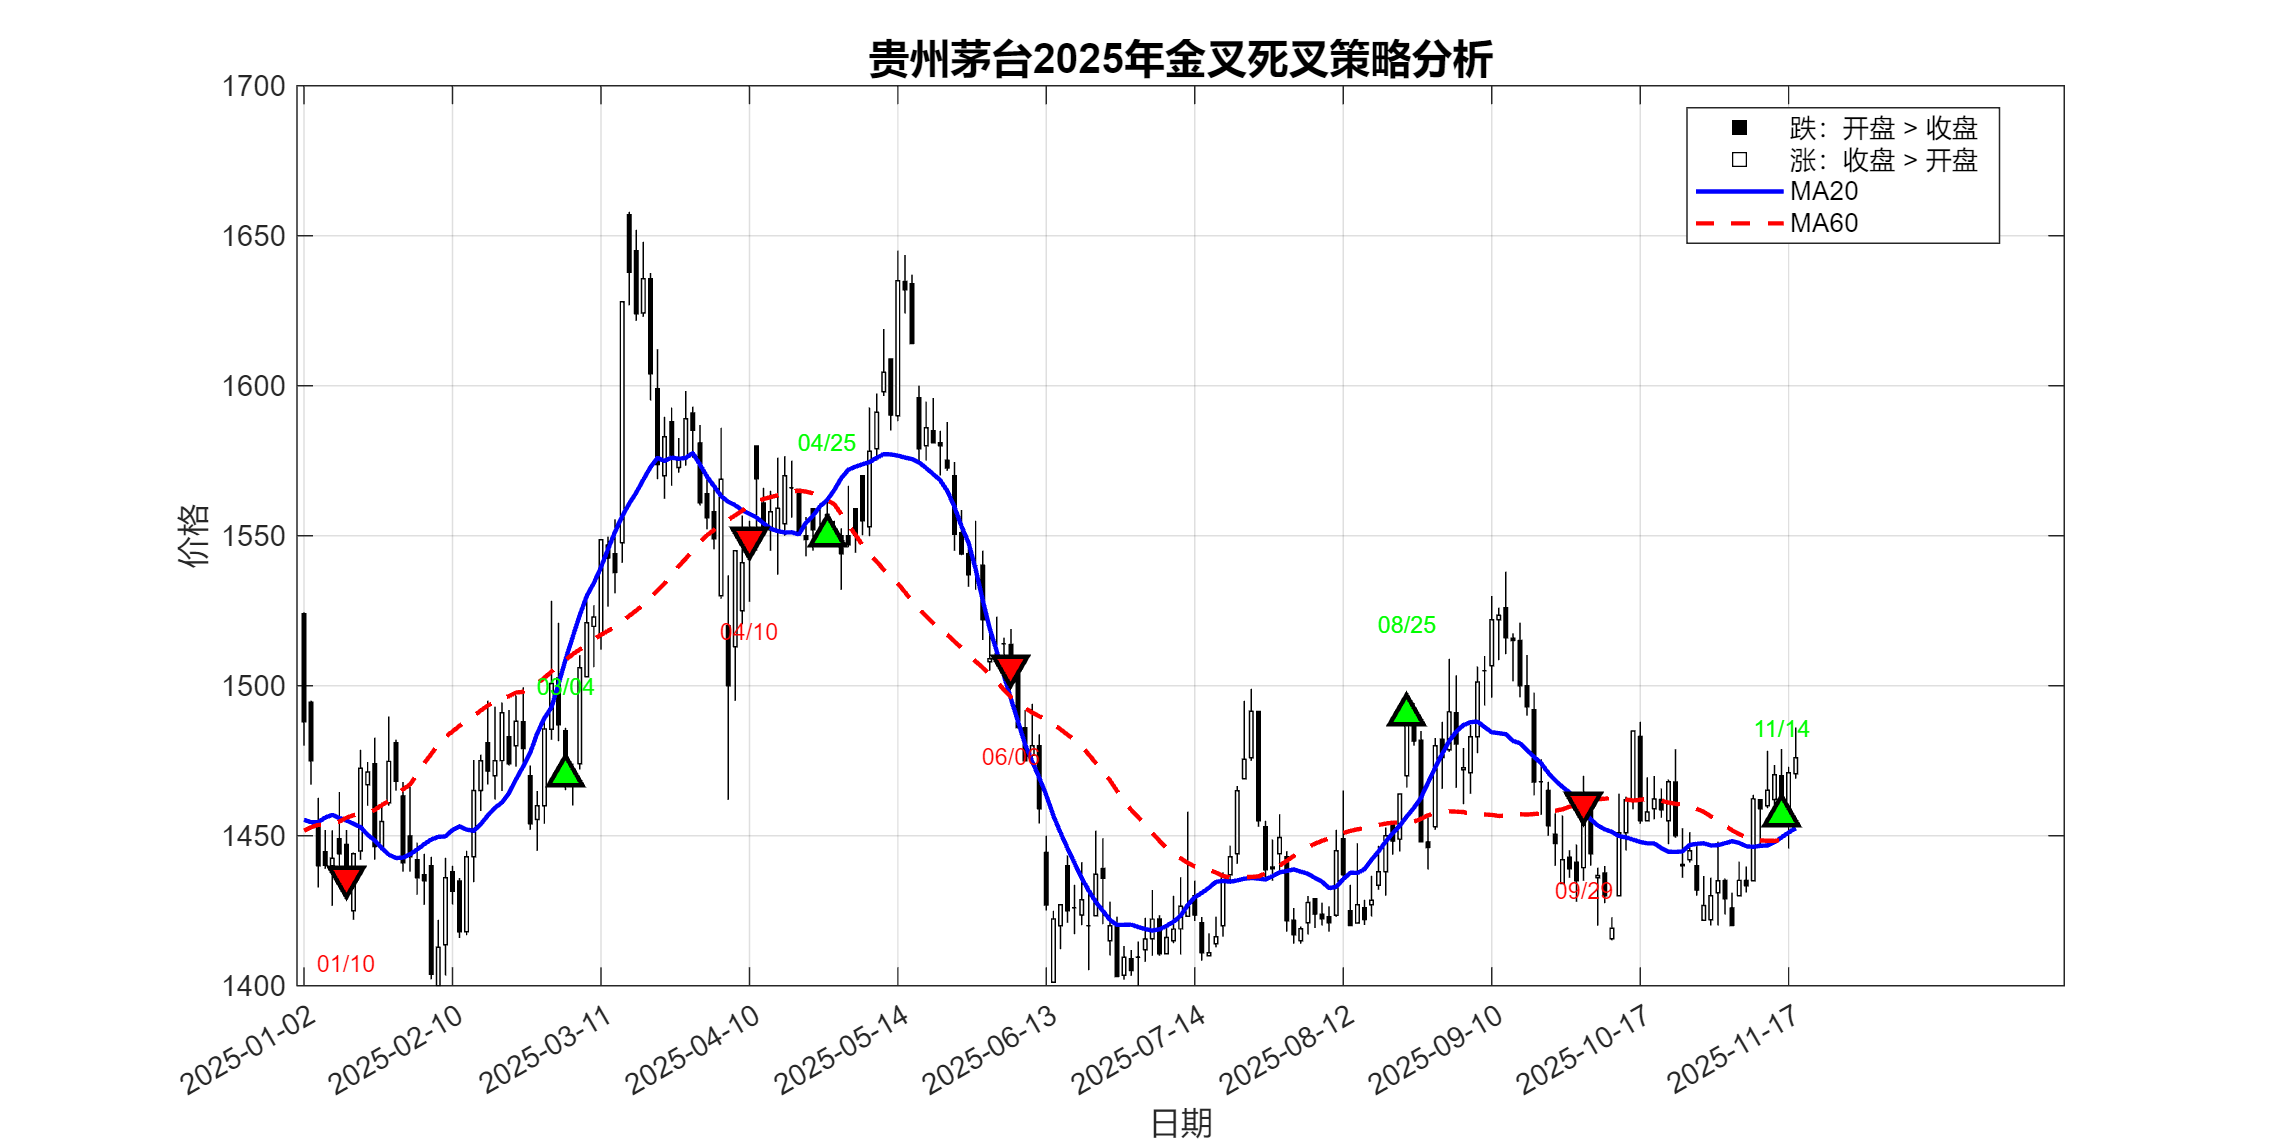

disp(result.MA20)
disp(result.MA60)
disp(result.BuySignals)
disp(result.SellSignals)

if isempty(result)
    fprintf('❌ 数据获取失败，请检查股票代码和网络连接\n');

    return;
end

plotStrategy2(result.Data, result, stockName);